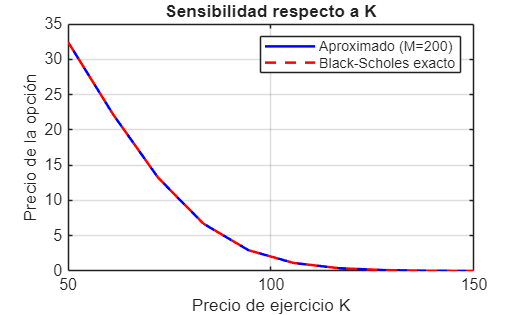

% Parámetros base (se mantienen fijos excepto el que se varía)
r_base     = 0.05;
sigma_base = 0.2;
K_base     = 100;
T_base     = 1;
S          = 80;
M_fijo     = 200;   % número de polinomios (puedes ajustar)

% Límite para integrales (suficientemente grande)
L = 10;

%% Sensibilidad en K
K_vals = linspace(50, 150, 10);
precio_aprox_K = zeros(size(K_vals));
precio_exacto_K = zeros(size(K_vals));

for idx = 1:length(K_vals)
    K = K_vals(idx);
    
    % Payoff en variable x = log(S)
    payoff = @(x) max(exp(x) - K, 0);
    
    % Coeficientes iniciales c0
    c0 = zeros(M_fijo+1, 1);
    for k = 0:M_fijo
        integrando = @(x) payoff(x) .* hermite(x, k) .* exp(-x.^2);
        valor_int = integral(integrando, -L, L, 'RelTol', 1e-8, 'AbsTol', 1e-10);
        norm_factor = 2^k * factorial(k) * sqrt(pi);
        c0(k+1) = valor_int / norm_factor;
    end
    
    % Matriz D (depende de r_base y sigma_base, que son fijos aquí)
    D = zeros(M_fijo+1, M_fijo+1);
    for i = 0:M_fijo
        for j = 0:M_fijo
            term1 = i * (sigma_base^2 - 2*r_base) * (i == j+1);
            term2 = -2 * i * sigma_base^2 * (j+1) * (i == j+2);
            term3 = r_base * (i == j);
            D(j+1, i+1) = term1 + term2 + term3;
        end
    end
    A = -D;
    
    % Solución en T
    c_T = expm(A * T_base) * c0;
    
    % Evaluación en S
    x_val = log(S);
    u_aprox = 0;
    for k = 0:M_fijo
        u_aprox = u_aprox + c_T(k+1) * hermite(x_val, k);
    end
    precio_aprox_K(idx) = u_aprox;
    precio_exacto_K(idx) = blsprice(S, K, r_base, T_base, sigma_base);
end
% Gráfica
figure;
plot(K_vals, precio_aprox_K, 'b-', 'LineWidth', 1.5); hold on;
plot(K_vals, precio_exacto_K, 'r--', 'LineWidth', 1.5);
xlabel('Precio de ejercicio K');
ylabel('Precio de la opción');
legend('Aproximado (M=200)', 'Black-Scholes exacto');
title('Sensibilidad respecto a K');
grid on;

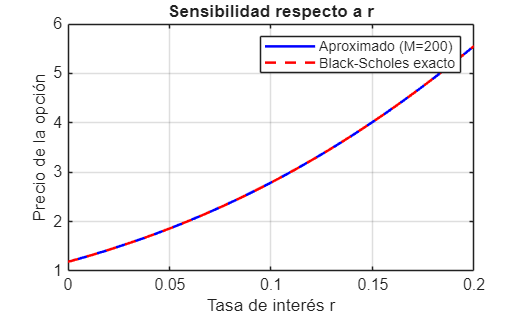


%% Sensibilidad en r
r_vals = linspace(0, 0.2, 40);
precio_aprox_r = zeros(size(r_vals));
precio_exacto_r = zeros(size(r_vals));

for idx = 1:length(r_vals)
    r = r_vals(idx);
    
    % Payoff con K_base fijo
    payoff = @(x) max(exp(x) - K_base, 0);
    
    % Coeficientes iniciales (dependen de K_base, no de r)
    c0 = zeros(M_fijo+1, 1);
    for k = 0:M_fijo
        integrando = @(x) payoff(x) .* hermite(x, k) .* exp(-x.^2);
        valor_int = integral(integrando, -L, L, 'RelTol', 1e-8, 'AbsTol', 1e-10);
        norm_factor = 2^k * factorial(k) * sqrt(pi);
        c0(k+1) = valor_int / norm_factor;
    end
    
    % Matriz D (depende de r y sigma_base)
    D = zeros(M_fijo+1, M_fijo+1);
    for i = 0:M_fijo
        for j = 0:M_fijo
            term1 = i * (sigma_base^2 - 2*r) * (i == j+1);
            term2 = -2 * i * sigma_base^2 * (j+1) * (i == j+2);
            term3 = r * (i == j);
            D(j+1, i+1) = term1 + term2 + term3;
        end
    end
    A = -D;
    
    c_T = expm(A * T_base) * c0;
    
    x_val = log(S);
    u_aprox = 0;
    for k = 0:M_fijo
        u_aprox = u_aprox + c_T(k+1) * hermite(x_val, k);
    end
    precio_aprox_r(idx) = u_aprox;
    precio_exacto_r(idx) = blsprice(S, K_base, r, T_base, sigma_base);
end

figure;
plot(r_vals, precio_aprox_r, 'b-', 'LineWidth', 1.5); hold on;
plot(r_vals, precio_exacto_r, 'r--', 'LineWidth', 1.5);
xlabel('Tasa de interés r');
ylabel('Precio de la opción');
legend('Aproximado (M=200)', 'Black-Scholes exacto');
title('Sensibilidad respecto a r');
grid on;

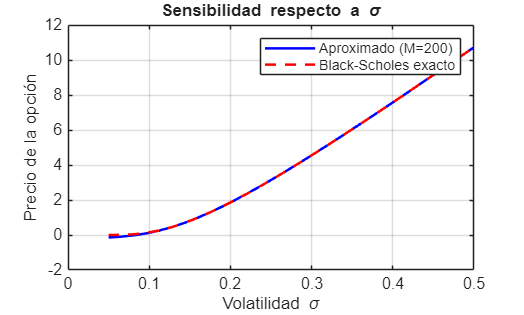


%% Sensibilidad en sigma
sigma_vals = linspace(0.05, 0.5, 30);
precio_aprox_sigma = zeros(size(sigma_vals));
precio_exacto_sigma = zeros(size(sigma_vals));

for idx = 1:length(sigma_vals)
    sigma = sigma_vals(idx);
    
    payoff = @(x) max(exp(x) - K_base, 0);
    
    % c0 (no depende de sigma)
    c0 = zeros(M_fijo+1, 1);
    for k = 0:M_fijo
        integrando = @(x) payoff(x) .* hermite(x, k) .* exp(-x.^2);
        valor_int = integral(integrando, -L, L, 'RelTol', 1e-8, 'AbsTol', 1e-10);
        norm_factor = 2^k * factorial(k) * sqrt(pi);
        c0(k+1) = valor_int / norm_factor;
    end
    
    % Matriz D (depende de sigma y r_base)
    D = zeros(M_fijo+1, M_fijo+1);
    for i = 0:M_fijo
        for j = 0:M_fijo
            term1 = i * (sigma^2 - 2*r_base) * (i == j+1);
            term2 = -2 * i * sigma^2 * (j+1) * (i == j+2);
            term3 = r_base * (i == j);
            D(j+1, i+1) = term1 + term2 + term3;
        end
    end
    A = -D;
    
    c_T = expm(A * T_base) * c0;
    
    x_val = log(S);
    u_aprox = 0;
    for k = 0:M_fijo
        u_aprox = u_aprox + c_T(k+1) * hermite(x_val, k);
    end
    precio_aprox_sigma(idx) = u_aprox;
    precio_exacto_sigma(idx) = blsprice(S, K_base, r_base, T_base, sigma);
end

figure;
plot(sigma_vals, precio_aprox_sigma, 'b-', 'LineWidth', 1.5); hold on;
plot(sigma_vals, precio_exacto_sigma, 'r--', 'LineWidth', 1.5);
xlabel('Volatilidad \sigma');
ylabel('Precio de la opción');
legend('Aproximado (M=200)', 'Black-Scholes exacto');
title('Sensibilidad respecto a \sigma');
grid on;

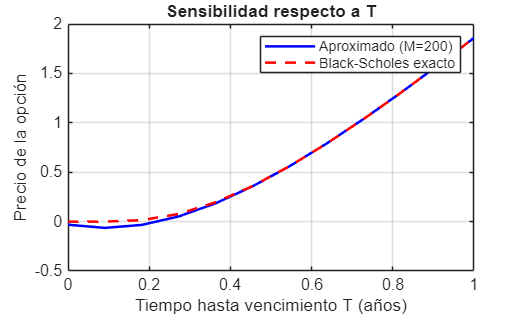



%% Sensibilidad en T
T_vals = linspace(0, 1, 12);
precio_aprox_T = zeros(size(T_vals));
precio_exacto_T = zeros(size(T_vals));

for idx = 1:length(T_vals)
    T = T_vals(idx);
    
    payoff = @(x) max(exp(x) - K_base, 0);
    
    % c0 (no depende de T)
    c0 = zeros(M_fijo+1, 1);
    for k = 0:M_fijo
        integrando = @(x) payoff(x) .* hermite(x, k) .* exp(-x.^2);
        valor_int = integral(integrando, -L, L, 'RelTol', 1e-8, 'AbsTol', 1e-10);
        norm_factor = 2^k * factorial(k) * sqrt(pi);
        c0(k+1) = valor_int / norm_factor;
    end
    
    % Matriz D (depende de r_base y sigma_base)
    D = zeros(M_fijo+1, M_fijo+1);
    for i = 0:M_fijo
        for j = 0:M_fijo
            term1 = i * (sigma_base^2 - 2*r_base) * (i == j+1);
            term2 = -2 * i * sigma_base^2 * (j+1) * (i == j+2);
            term3 = r_base * (i == j);
            D(j+1, i+1) = term1 + term2 + term3;
        end
    end
    A = -D;
    
    c_T = expm(A * T) * c0;
    
    x_val = log(S);
    u_aprox = 0;
    for k = 0:M_fijo
        u_aprox = u_aprox + c_T(k+1) * hermite(x_val, k);
    end
    precio_aprox_T(idx) = u_aprox;
    precio_exacto_T(idx) = blsprice(S, K_base, r_base, T, sigma_base);
end

figure;
plot(T_vals, precio_aprox_T, 'b-', 'LineWidth', 1.5); hold on;
plot(T_vals, precio_exacto_T, 'r--', 'LineWidth', 1.5);
xlabel('Tiempo hasta vencimiento T (años)');
ylabel('Precio de la opción');
legend('Aproximado (M=200)', 'Black-Scholes exacto');
title('Sensibilidad respecto a T');
grid on;